# **pEllipticD**

Legendre form of the elliptic integral D

## Definition


$$D\left(\phi \left|m\right.\right)\equiv \int_0^{\phi } \frac{\sin^2 \theta \;\;d\theta \;}{\sqrt{1-m\;\sin^2 \theta }}$$



$$D\left(\phi ,k\right)\equiv D\left(\phi \left|k^2 \right.\right)$$


where $\phi \;$is the argument, *k *is the modulus,  *m *is the parameter.

Domain: $1-m\sin^2 \phi \ge 0$ . If $-\infty <m\le 1$(or $\left.|k|\le 1\right)$ then $-\infty \le \phi \le \infty$. If $m>1$ (or $k>1$) then  $\left|\phi \right|<{\mathrm{sin}}^{-1} \left(1/\sqrt{m}\right)$. For the specified domain, the  codomain is real numbers.

Basic features:

$D\left(-\phi \left|m\right.\right)=-D\left(\phi \left|m\right.\right)$   (odd)

 $D\left(\textrm{n}\pi \pm \phi \left|m\right.\right)=2n\;D\left(m\right)\pm D\left(\phi \left|m\right.\right),\;\;\;\left|\phi \right|\le \pi /2$  (quasi-periodic)

Special values:

$D\left(0\left|m\right.\right)=0$,   $D\left(\frac{\pi }{2}\left|m\right.\right)=D\left(m\right)$

$D\left(\phi \left|-\infty \right.\right)=0$,   $D\left(\phi \left|0\right.\right)=\frac{2\phi -\sin \left(2\phi \right)}{8}$,  $D\left(\phi \left|1\right.\right)={\mathrm{tanh}}^{-1} \left(\mathrm{sin}\phi \right)-\mathrm{sin}\phi$

Identities:


$$D\left(\phi \left|m\right.\right)=\mathit{\mathbf{D}}\left(\sin \left(\phi \right)\left|m\right.\right),\left|\phi \right|\le \pi /2$$



$$D\left(\phi \left|m\right.\right)=\frac{F\left(\phi \left|m\right.\right)-E\left(\phi \left|m\right.\right)}{m}$$


where **D **is the Jacobi form of the elliptic integral D, *E* and *F* are the Legendre form of the elliptic integrals of 1st and 2nd kind ([3-4])

## Syntax

Y = pEllipticD(PHI,K)

y = pelD(phi,k)

Y = mpEllipticD(PHI,M)

y = mpelD(phi,m)

## Description

**Y = pEllipticD(PHI,K)** returns the Legendre form of the elliptic integral  $D\left(\phi ,k\right)$ for each element of the arrays PHI (the argment) and K (the modulus). PHI and K must be real and the same size or any of them can be scalar. **pEllipticD** is the wrapper function which calls the functions **pelD** element-wise via the function **ufun2**.

**y = pelD(phi,k) **returns the value of  the Legendre form of the elliptic integral  $D\left(\phi ,k\right)$ for the argument phi and the modulus k. It is assumed that  the input arguments are real scalars without check. y is NaN if any of   the input arguments is invalid or convergence failed. **pelD** is the wrapper function which calls the functions **mpelD**.

**Y = mpEllipticD(PHI,M)** returns the Legendre form of the elliptic integral  $D\left(\phi \left|m\right.\right)$ for each element of the arrays PHI (the argument) and M (parameter). PHI and M must be real and the same size or any of them can be scalar. **mpEllipticD** is the wrapper function which calls the functions **mpelD** element-wise via the function **ufun2**.

**y = mpelD(phi,m)** returns the value of the Legendre form of the elliptic integral $D\left(\phi \left|m\right.\right)$ for  the argument phi and the parameter m. It is assumed that the input arguments are real scalars without check. y is NaN if any of  the input arguments is invalid or convergence failed.  **mpelD **call the Carlson's function **rd **for calculation of $D\left(\phi \left|m\right.\right)$ ([1-2]).

## Precision

## **Numerical Examples**

**Scalar input**

format long
k = 0.5;
phi = pi/6;
[pelD(phi,k), pEllipticD(phi,k), mpelD(phi,k^2), mpEllipticD(phi,k^2)]

ans =    0.046186768767871   0.046186768767871   0.046186768767871   0.046186768767871


Accuracy. 

fprintf('%.16g\n',mpelD(pi/4,1/2)) %Maple 18D  0.1556627441431676 1

0.1556627441431676


Special values

m = 0.5;
phi = pi/9;
mpEllipticD(-phi,m) + mpEllipticD(phi,m)

ans = 0

mpEllipticD(0,m)

ans = 0

disp(mpEllipticD(pi/2,m) - mEllipticD(m))

     0



disp(pEllipticD(phi,0) - (phi/2 -sin(2*phi)/4))

    -1.214306433183765e-17



disp(pEllipticD(phi,1) - atanh(sin(phi)) + sin(phi))

     5.551115123125783e-17



pEllipticD(phi,-inf)

ans = 0

Identities

m=-10^4;
phi = 0.499*pi; % |phi|<=pi/2
disp(mpelD(phi,m) - melD(sin(phi),m))

    -1.509209424099822e-16



phi = pi/3; % |phi|<=pi/2
k = 0.5; % |k|<=1
n = 2;
disp(pelD(phi+n*pi,k)-(pelD(phi,k)+2*n*elD(k))) % periodicity

    -4.440892098500626e-16



k = 0.99995;
phi = pi/8;
disp(pEllipticD(phi,k) - (pelF(phi,k)- pelE(phi,k))/k^2)

     3.469446951953614e-18



**Vector input**

format short
k = 0.5;
PHI = [pi/3, pi/4, 1, pi/2];
disp(pEllipticD(PHI,k) - (pEllipticF(PHI,k)-pEllipticE(PHI,k))/k^2)

   1.0e-15 *

   -0.1665    0.5274    0.3886    0.1110



**Matrix input**

Test identity $D\left(\phi \left|m\right.\right)=\mathit{\mathbf{D}}\left(\sin \left(\phi \right)\left|m\right.\right),\left|\phi \right|\le \pi /2$

PHI = [pi/6 pi/4 3*pi/8; -pi/6 -pi/4 -3*pi/8];
M = [1/4 1 1/9; -0.1 0.2 10.1];
disp(mpEllipticD(PHI,M) - mEllipticD(sin(PHI),M))

   1.0e-16 *

         0   -0.2776         0
         0         0       NaN



## **Graphs **

**Example 1**

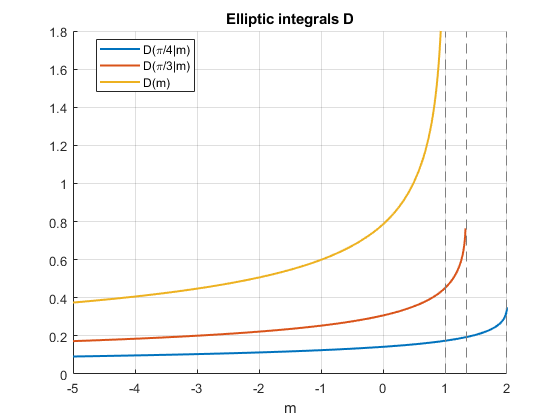

figure
hold on
fplot(@(m)mpEllipticD(pi/4, m),'LineWidth',1.5)
fplot(@(m)mpEllipticD(pi/3, m),'LineWidth',1.5)
fplot(@(m)mEllipticD(m),'LineWidth',1.5)
xlabel('m')
grid on
title('Elliptic integrals D')
legend('D(\pi/4|m)', 'D(\pi/3|m)', 'D(m)', 'Location', 'Best')
hold off

**Example 2**

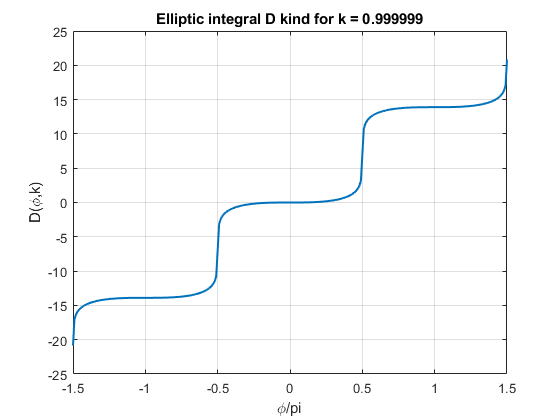

figure
phi=-1.5:0.01:1.5;
k = 0.999999;
plot(phi,pEllipticD(pi*phi,k),'LineWidth',1.5)
xlabel('\phi/pi')
ylabel('D(\phi,k)')
%xlim([-1.1 1.1])
%ylim([-3 3])
title(sprintf('Elliptic integral D kind for k = %g',k))
grid on

**Example 3**

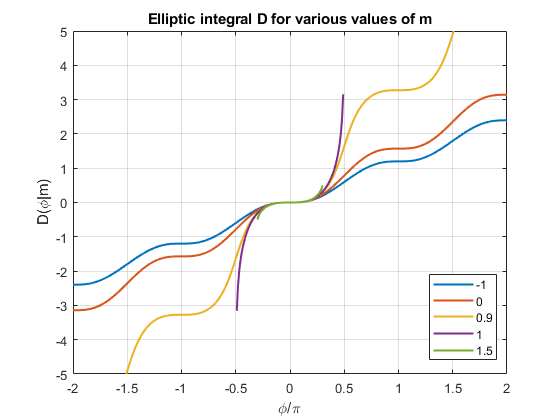

figure
PHI = -2:0.01:2;
M = [-1,0,0.9, 1,1.5];
SN = zeros(length(M),length(PHI));
clg{length(M)}=[];
for i = 1:length(M)
     clg{i} = num2str(M(i));
    SN(i,:) = mpEllipticD(pi*PHI,M(i));
end
plot(PHI,SN,'LineWidth',1.5)
axis([min(PHI) max(PHI) -5 5])
grid on
legend(clg{1:length(M)},'Location','Best')
title('Elliptic integral D for various values of m')
xlabel('\phi/\pi')
ylabel('D(\phi|m)')

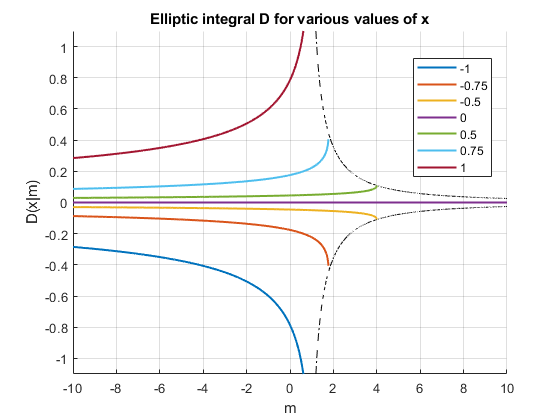

figure
hold on
M = -10:0.01:10;
X = [-1,-0.75,-0.5,0,0.5,0.75,1];
SN = zeros(length(X),length(M));
clg{length(X)}=[];
for i = 1:length(X)
     clg{i} = num2str(X(i));
    SN(i,:) = mEllipticD(X(i),M);
end
plot(M,SN,'LineWidth',1.5)
axis([min(M) max(M) -1.1 1.1])
M = 0:0.01:10;
D = mEllipticD(1./sqrt(abs(M)),M);
plot(M,D,'k-.')
plot(M,-D,'k-.')
grid on
legend(clg{1:length(X)},'Location','Best')
title('Elliptic integral D for various values of x')
xlabel('m')
ylabel('D(x|m)')
hold off

**Example 4**

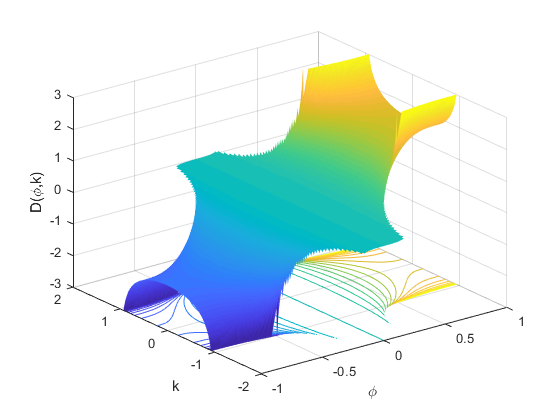

figure
phi=-1:0.01:1;
k=-2:0.01:2;
[PHI,K]=meshgrid(phi,k);
hs=surfc(PHI,K,pEllipticD(pi*PHI,K),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -3;
hc.LineWidth = 0.5;
hc.LevelList = -3:0.2:3;
caxis([-3 3])
view(3);
xlabel('\phi')
ylabel('k')
zlabel('D(\phi,k)')
zlim([-3 3])
grid on

**Example 5**

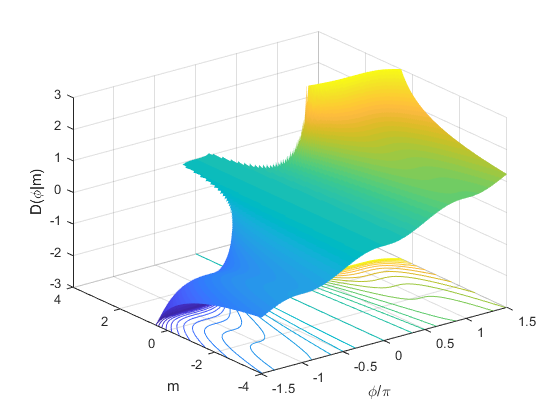

figure
phi=-1.5:0.01:1.5;
m=-4:0.01:4;
[PHI,M]=meshgrid(phi,m);
hs=surfc(PHI,M,mpEllipticD(pi*PHI,M),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -3;
hc.LineWidth = 0.5;
hc.LevelList = -3:0.2:3;
view(3)
caxis([-3 3])
xlabel('\phi/\pi')
ylabel('m')
zlabel('D(\phi|m)')
zlim([-3 3])
grid on

**Example 6**

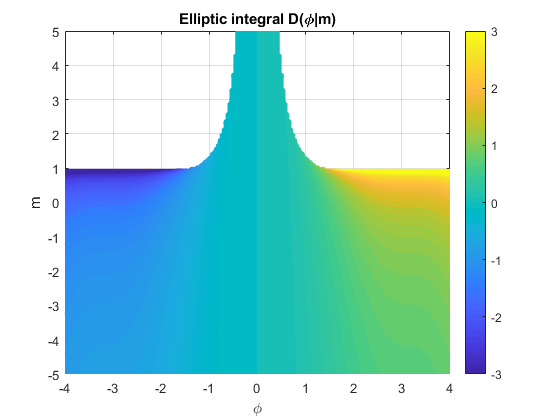

figure
f = @(phi,m)mpEllipticD(phi,m);
fcontour(f,[-4 4 -5 5],'Fill','on','LevelList',-3:0.1:3,'MeshDensity',200)
title('Elliptic integral D(\phi|m)')
colorbar
xlabel('\phi')
ylabel('m')
grid on

**Example 7**

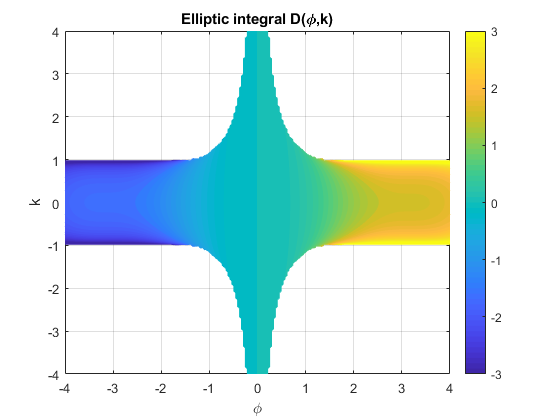

figure
f = @(phi,k)pEllipticD(phi,k);
fcontour(f,[-4 4 -4 4],'Fill','on','LevelList',-3:0.1:3,'MeshDensity',200)
title('Elliptic integral D(\phi,k)')
colorbar
xlabel('\phi')
ylabel('k')
grid on

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Elliptic Integrals, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/19)

[Elliptic integrals, Wikipedia](https://en.wikipedia.org/wiki/Elliptic_integral)

[Higher Transcendental Functions](http://apps.nrbook.com/bateman/Vol2.pdf) 

## **References**

[1] B.C. Carlson, Computing Elliptic Integrals by Duplication. Numerische Mathematik 33, 1-16, 1979.

[2] W.H. Press et al., Numerical Recipes, 3rd ed., Cambridge, 2007

[3] A. Erd´elyi et al., Higher Transcendental Functions Vol. II, California Institute of

Technology - Bateman Manuscript Project, 1953-1955 McGraw-Hill Inc. 

[4] E.Jahnke, F. Emde, Tables of Functions, 4th ed, Dover,  1945

## See Also